## Sintesis mu - lateral

Pesos Wp

clear
load('modelo_lin.mat');

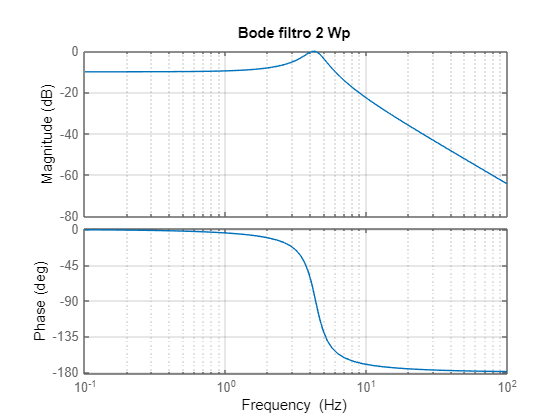


G = latmod([2:5],:);
fc = 6;
fs = 1;
[b1,a1] = cheby1(2,10,fc*2*pi*fs,'s');
[A,B,C,D] = tf2ss(b1,a1);
wp1 = ss(A,B,C,D);

h = bodeplot(tf(b1,a1));
setoptions(h,'FreqUnits', 'Hz', 'grid', 'on');
title("Bode filtro 2 Wp");

[b2,a2] = cheby1(2,10,fc*2*pi*fs,'s');
[A,B,C,D] = tf2ss(b2,a2);
wp2 = ss(A,B,C,D);

h = bodeplot(tf(b2,a2));
setoptions(h,'FreqUnits', 'Hz', 'grid', 'on');
title("Bode filtro 2 Wp");

[b1,a1] = cheby1(2,10,fc*2*pi*fs,'s');
Wd = ss([5,0;0,1.2]);
Wi = tf2ss(b1,a1);
Wr = ss([0.0005 0 0 0; 0 0.000002 0 0; 0 0 0.0000001 0; 0 0 0 0.0000001]);
Wn = ss([0.5,0,0,0;0,0.5,0,0;0,0,0.5,0;0,0,0,0.5]);
Wp = ss([wp1,0,0,0;0,wp2,0,0;0,0,wp1,0;0,0,0,wp2]);
p1 = ureal('p1',0.5,'pe',1); 
p2 = ureal('p2',0.5,'plusm',[-.5 1.2]); 
delta_a = eye(4);
Wa_ = [p1,p1;p2,p2;p1,p2;p1,p2];
Wa = ss(eye(4)*Wa_);
Wu = ss(eye(2));
systemnames = 'Wd Wr Wn Wp Wa Wu G';
inputvar = '[d(2); r(4); n(4); u(2)]';
outputvar = '[Wu; Wp; r-G-n-Wa]';
input_to_Wd = '[d]';
input_to_Wn = '[n]';
input_to_Wr = '[r]';
input_to_Wp = '[G-r]';
input_to_Wa = '[u+Wd]';
input_to_Wu = '[u]';
input_to_G = '[d+u]';
sysoutname = 'P'; cleanupsysic = 'yes';
sysic;
[Klat,CL,gamma] = musyn(P,4,2)



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           3.427        3.293        3.317            28
    2           3.246        2.776         2.79            26
    3            2.67        2.553         2.56            30
    4           2.504        2.441        2.464            28
    5           2.426        2.379        2.402            30
    6           2.392        2.342        2.362            30
    7           2.342        2.305        2.335            40
    8           2.316        2.286         2.31            36
    9           2.303        2.273        2.297            30
   10           2.278        2.254        2.269            30

Best achieved robust performance: 2.25


Klat =
 
  A = 
                x1          x2       

CL = 2.2541

gamma = 10×1 struct array with fields:
    gamma
    K
    KInfo
    PeakMu
    DG
    PeakMuFit
    FitOrder
    dr
    dc
    PSI


## Prueba con ruido blanco y perturbaciones    

Wa = ss(eye(4)*Wa_);
systemnames = 'G Klat Wa';
inputvar = '[d(2); r(4); n(4)]';
outputvar = '[G;r-G;Klat]';
input_to_G = '[d+Klat]';
input_to_Klat = '[r-G-n]';
input_to_Wa = '[Klat+d]';
sysoutname = 'latCL'; cleanupsysic = 'yes';
sysic;

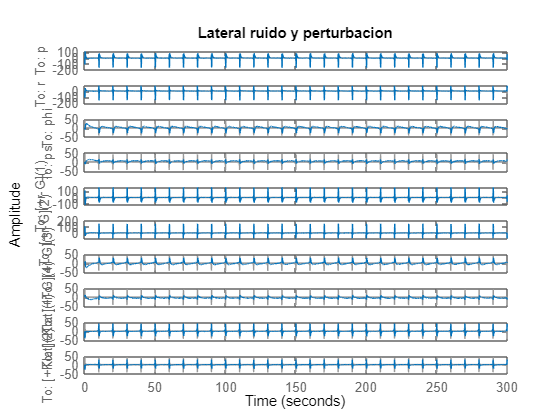

m = 10000;
tf = 60*5;
freqz = (0:0.1:6)';
m = 10000;
tf = 60*5;
t = linspace(0,tf,m);
%perturbacion
dLong = [sin(freqz*pi*2.*t)]';
dLong = sum(dLong,2);
t = linspace(0,tf,m);
%Se hace perturbacion con todas las frecuencias en el ancho de banda
dLat = [dLong,dLong];
rLat = [zeros(m,2),ones(m,2)];
nLat = wgn(m,4,10*log10(0.001));
wLat = [dLat,rLat,nLat];
figure
lsim(latCL,wLat,t)
title("Lateral ruido y perturbacion")


nsamp = 100

nsamp = 100

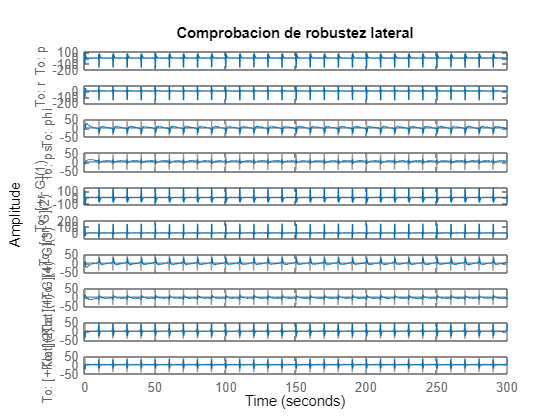

figure
lsim(usample(latCL,nsamp),wLat,t)
title('Comprobacion de robustez lateral')

Similarmente, al acercar lo suficiente a la grafica, se observa que hay robustez. En la ultima grafica se ve esa distrocion de la señal de entrada porque la el eje y esta entre -1 y 1. No cambio la entrada.

## Prueba de la señal de control entre -40 y +40 grados para phi

En la ultima señal (theta) se aprecia que se cumple el rango establecido. Tambien se aprecia que el sistema se demora aproxiamadamento 0.4 segundos en alcanzar la referencia solicitada. Todo esto aun con las perturbaciones y ruido presentes.

entrada = ones(m,1)*-40;
entrada(500:1000) = 40;
rLat = [zeros(m,2),entrada,ones(m,1)];
wLat = [dLat,rLat,nLat];
figure;
lsim(latCL,wLat,t);
title("Simulacion lateral probando señal de control +-40 grados para phi");

## Damping

damp(latCL)

Bode del ruido n vs la salida y

h = bodeplot(latCL);
setoptions(h,'FreqUnits', 'Hz', 'grid', 'on', 'OutputVisible', {'off','off','on','on','off','off','off','off','off','off'}, ...
    'InputVisible',{'off','off','off','off','off','off','on','on','on','on'});
title("Bode del ruido n vs la salida y - Eje longitudinal ciclo cerrado")

Bode de S

h = bodeplot(latCL);
setoptions(h,'FreqUnits', 'Hz', 'grid', 'on', 'OutputVisible',{'off','off','on','on'}, ...
    'InputVisible', {'off','off','on','on','on','on','off','off','off','off'});
title("Bode de S - Eje longitudinal ciclo cerrado")

Bode de KS

h = bodeplot(latCL);
setoptions(h,'FreqUnits', 'Hz', 'grid', 'on', 'OutputVisible',{'off','off','off','off','on','on','on','on','off','off'}, ...
    'InputVisible', {'off','off','off','off','off','off','on','on','on','on'});
title("Bode de KS - Eje longitudinal ciclo cerrado")

Bode de T

h = bodeplot(latCL);
setoptions(h,'FreqUnits', 'Hz', 'grid', 'on', 'OutputVisible',{'on','on','off','off','off'}, ...
    'InputVisible', {'off','on','on','off','off'});
title("Bode de T - Eje longitudinal ciclo cerrado")

Bode de la perturbacion (d) a la salida (y)

h = bodeplot(latCL);
setoptions(h,'FreqUnits', 'Hz', 'grid', 'on', 'OutputVisible',{'on','on','off','off','off'}, ...
    'InputVisible', {'on','off','off','off','off'});
title("Bode de la perturbacion (d) a la salida (y) - Eje longitudinal ciclo cerrado")

Graficar valores propios

sigma(longCL,'r')
x2 = pi;
x1 = 0;
cota = (R*J/k)*a*x2  - (x2*(k+(R*B*L^2)/k) + (R*M*L)*cos(x1)/k)
ueq = -cota